BASE_DIR='/Users/erik/Dropbox/Projects/Machine_Learning/data/'

BASE_DIR = '/Users/erik/Dropbox/Projects/Machine_Learning/data/'

m = 2; % slope
b = 10; % y intercept
N = 2000; % Total number of samples
n = 100; % Samples per datapoint 
P = zeros(N,2)

P =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


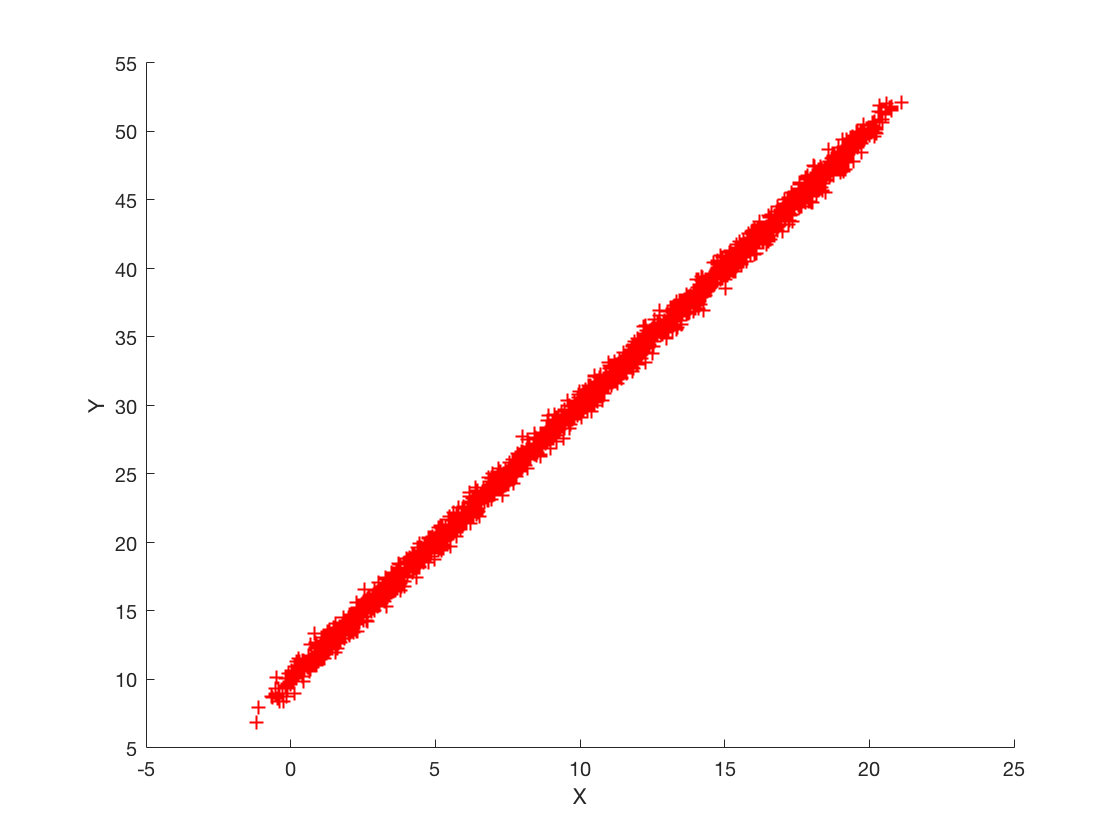

sigma = 0.5;
for idx = 1:N
    x = round(idx/n) + sigma*randn(1);
    mu=m*x+b;
     
    % values are true + noise
    P(idx,1) = x;
    P(idx,2) = normrnd(mu,sigma,1);
end

figure(1);
hold on;
xlabel('X')
ylabel('Y')
scatter(P(1:N,1),P(1:N,2),'r+');

% X=horzcat((1:N)',y');
csvwrite(BASE_DIR+"line-dense.csv",P);

